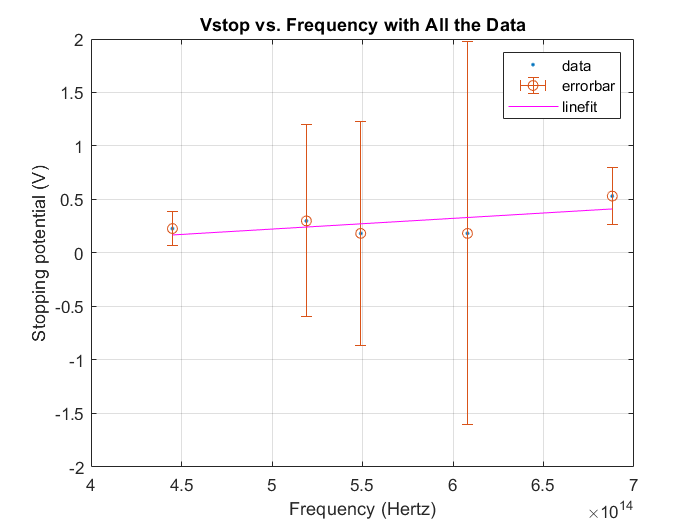

plot(freq,Vstop,'.')
hold on
grid on

%ERRORBAR
yerror=[0.156 0.8965 1.050 1.789 0.2669];
errorbar(freq,Vstop,yerror,'both','o')

%RAW LINE FIT
%Linear model Poly1:
 %    f(x) = p1*x + p2
%Coefficients (with 95% confidence bounds):
 %      p1 =   1.001e-15  (-1.267e-15, 3.269e-15)
 %      p2 =     -0.2769  (-1.564, 1.011)

%Goodness of fit:
%  SSE: 0.05133
 % R-square: 0.3968
 % Adjusted R-square: 0.1958
 % RMSE: 0.1308
 p1 =   1.001e-15;
 p2 =     -0.2769;
 f=p1.*freq+p2;
 
 plot(freq,f,'m')
%%labeling
legend({'data','errorbar','linefit'})
title('Vstop vs. Frequency with All the Data')
xlabel('Frequency (Hertz)')
ylabel('Stopping potential (V)')


hold off

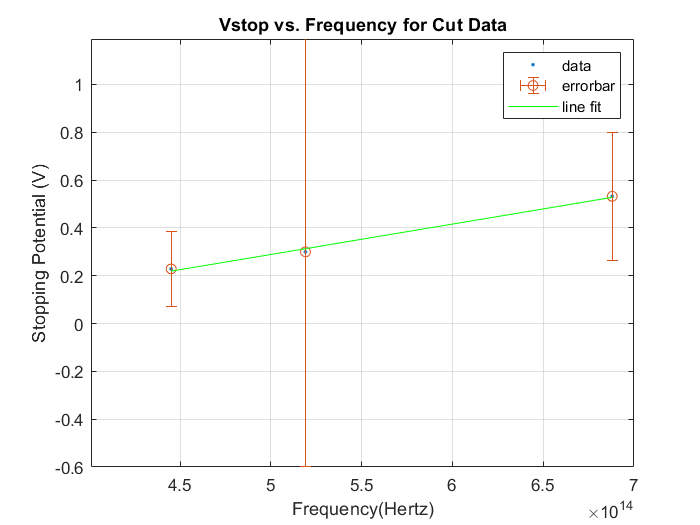


%%CREATING A BETTER FIT BY ELIMINATING TURQUOISE AND GREEN LIGHT

plot(freqC,Vcorrected,'.')
hold on
grid on

%ERRORBAR
yerrorC=[0.156 0.8965  0.2669];
errorbar(freqC,Vcorrected,yerrorC,'both','o')






%%CORRECTED LINE FIT

%Linear model Poly1:
 %    f(x) = p3*x + p4
%Coefficients (with 95% confidence bounds):
 %      p3 =    1.27e-15  (6.258e-17, 2.478e-15)
  %     p4 =      -0.346  (-1.022, 0.3304)

%Goodness of fit:
 % SSE: 0.0002804
 % R-square: 0.9944
 % Adjusted R-square: 0.9889
 % RMSE: 0.01674
  p3 =    1.27e-15;
  p4 =      -0.346 ;
 g=p3.*freqC+p4;
 plot(freqC,g,'g')
 
 xlim([400828729281768 700000000000000])
ylim([-0.60 1.19])
legend({'data','errorbar','line fit'})
title('Vstop vs. Frequency for Cut Data')
xlabel('Frequency(Hertz)')
ylabel('Stopping Potential (V)')
 
 
 
 hold off